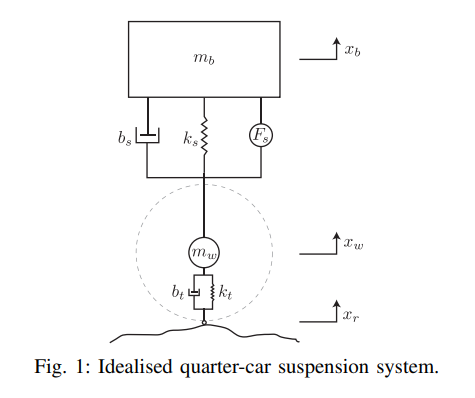

We use the above quater car mode with the following parameters


$$m_b =450\;\mathrm{kg};k_b =13000\;\frac{N}{m};$$

$$b_s =1100\;\frac{\textrm{Ns}}{s}$$



$$m_w =70\;\textrm{kg};k_t =140,000\;\frac{N}{m};b_t =755\;\frac{\textrm{Ns}}{m}$$



$$x_r =x_{\textrm{r0}\;} \sin \left(\textrm{wt}\right)$$


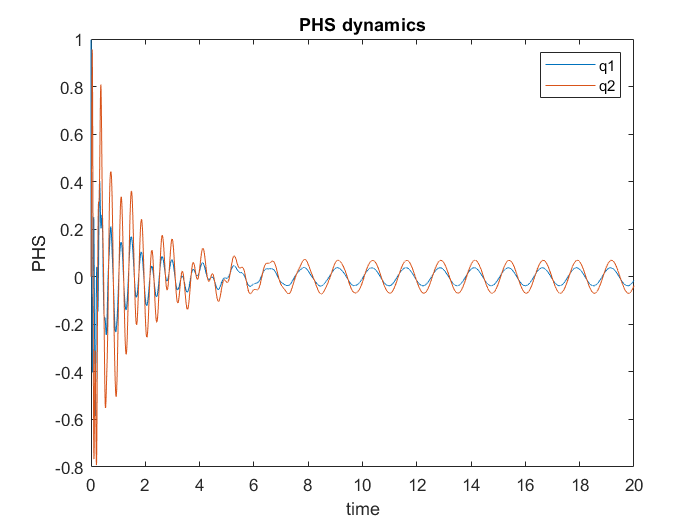

clc
clear
close all

tfinal = 20; dt = 0.001; % simulation parameters


mb=2.45; ks=980; bs=7.5;
mw=1; kt=2500; bt=5;

M = [mw+mb mb;mb mb];
G1 = [bt;0]; G2 = [-1;0]; 
D = diag([bt,bs]); G = [0;1];
A_hat = [-D -eye(2);eye(2) zeros(2)];
B_hat = [G;zeros(2,1)];
xr0 = 1; w=5;

x0 = [0;1;0;1]; x = x0; t = 0; H_sys = 0; % initial condition

p10 = mb*x(2); p1 = p10; p20 = mw*x(4); p2 = p20; p=[p1;p2];
q10 = x(1); q1 = q10; q20 = x(3); q2 = q20; q=[q1;q2];
xw = q10 + xr0; xb = q20 + xw; xr = 0;

p_hat = p - G1*xr0; q_hat = q - G2*xr0;
phs0 = [p_hat;q_hat]; phs = phs0; 

PHS = []; T = []; % initialize memory
Q=[]; Xb=[]; Xw=[]; Xr=[];
while (t <= tfinal)
    T = [T,t]; PHS = [PHS,phs];
    Q = [Q,q]; Xb=[Xb,xb]; Xw=[Xw,xw]; Xr=[Xr,xr];
    xr = xr0*sin(w*t);
    K = [0.5*p_hat(1)+bt*xr; 0.5*p_hat(2)];
    KE_hat = K'*inv(M)*K;
    PE_hat = 0.5*kt*(q_hat(1)-xr)^2 + 0.5*ks*q_hat(2)^2;
    H_hat = KE_hat + PE_hat;

    %u = lambda*(H_sys - k*^2/2)/2;
    u=0;
    phs = phs + dt*(A_hat*([inv(M)*[phs(1)+bt*xr;phs(2)];(kt*(phs(3)-xr));phs(4)*ks]) + B_hat*u); %diff eqn

    q = [phs(3);phs(4)]+G2*xr; 
    xw = q(1) + xr;
    xb = q(2) + xw;
    t = t + dt; % time increment
end

figure(1)
plot(T,Q);
ylabel('PHS')
xlabel('time')
legend('q1','q2')
title('PHS dynamics')

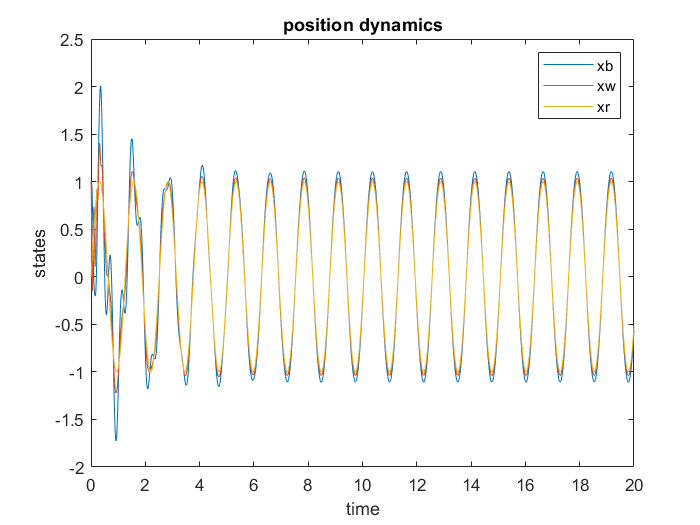


figure(2)
plot(T,Xb); hold on;
plot(T,Xw); hold on;
plot(T,Xr);
ylabel('states')
xlabel('time')
legend('xb','xw','xr')
title('position dynamics')
hold off



% figure(3)
% plot(T(2:end),PM); hold on;
% plot(T(2:end),PK); hold on;
% plot(T(2:end),PR);
% ylabel('Power states')
% xlabel('time')
% legend('Pm','Pk','Pr')
% title('Power dynamics')
% hold off
